clear;
%{**************************** 1 *****************************%}

%{
******************** 
******** a *********
********************
%}
% mögliche Symbole
M = 16;

% 16 Symbole sind mit 4 Bits darstellbar
bitsPerSymbol = log2(M);
bitsPerSec = 10^6;

Rs = bitsPerSec / bitsPerSymbol; % Bd
fprintf("Rs = %i \n",Rs);

Rs = 250000 



%{
******************** 
******** b *********
********************
%}

% Sendeleistung
S = 1;
% Phasen im Einheitskreis
% grad
% gamma = 360 / M;
% radiant
gamma = (2*pi) / M;
alpha = (pi - gamma) / 2;
a_psk = 2 * S * sin(gamma/2);
fprintf("a_psk = %f \n", a_psk);

a_psk = 0.390181 


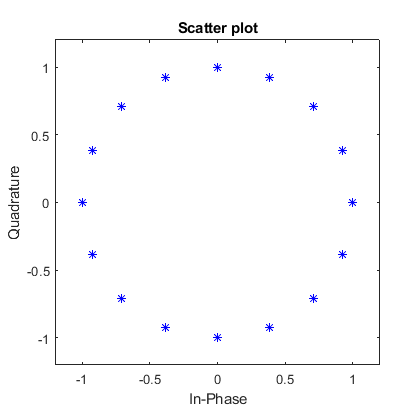

data = randi([0 M-1], 1000, 1);
symgray = pskmod(data, M, 0,'gray');
scatterplot(symgray, M, 0, 'b*');
axis([-1.2 1.2 -1.2 1.2]);


syms a;
s1 = (a/2)^2 + (a/2)^2;
s2 = (a/2)^2 + (3*a/2)^2;
s3 = (3*a/2)^2 + (3*a/2)^2;
eqn = (4*s1 + 8*s2 + 4*s3) / M == S;
fprintf("Formel = "); disp(eqn);

Formel = 

$$\frac{5\,a^{2}}{2}=1$$

a_qam = vpasolve(eqn, a, [0, Inf]); % a_qam = sqrt((2*S)/5)
fprintf("a_qam = %f", a_qam);

a_qam = 0.632456

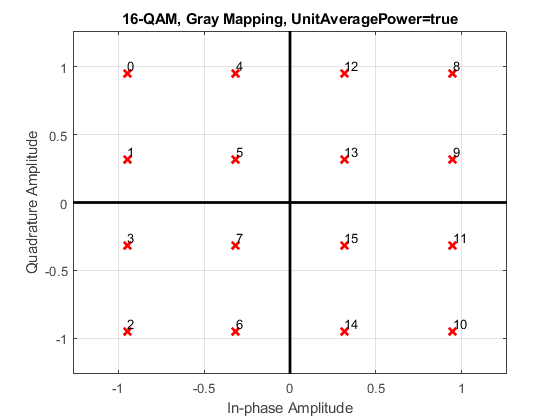

x = randi([0 M-1],1000,1);
qammod(x, M,'gray','UnitAveragePower', true,'PlotConstellation', true);

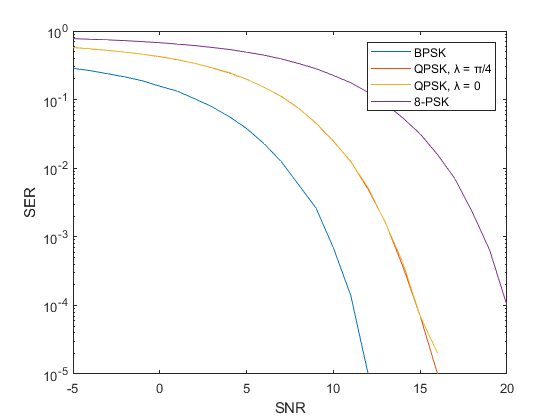


%{
******************** 
******** c *********
********************
%}

% Die QAM hat eine geringere Bitfehlerwahrscheinlichkeit, weil der Abstand
% zwischen 2 Symbolen größer ist als bei der PSK.

%{**************************** 2 *****************************%}
figure;

S = 1;
mu = 0;
symbols = 100000;
maxRadiant = [pi/2 pi/4 pi/4 pi/8];
dbSNR = -5:20;

SNR = 10.^(dbSNR./10);
N = S./SNR;
sigma = sqrt(N);
errors = zeros(1, length(sigma));

for i=1:4
    errors(:) = 0;
    
    for j = 1:length(SNR)
        N = normrnd(mu, sigma(j), symbols, 2);
        N_Re = 1+ N(:,1);
        N_Im = 1i * N(:,2);
        
        a = N_Re(:) + N_Im(:);
        rads = angle(a);
        
        err = sum(rads(:) > maxRadiant(i)) + sum(rads(:) <= -maxRadiant(i));
        errors(1, j) = errors(1, j) + err;
    end
    
    SER = errors./symbols;
    semilogy(dbSNR, SER);
    hold on;
end

legend('BPSK', 'QPSK, λ = π/4','QPSK, λ = 0','8-PSK');
xlabel('SNR');
ylabel('SER');
hold off;

% alte Lösung
%     betragN = 1 + normrnd(mu, sigma(j), symbols, 1);
%     winkelN = abs(wrapToPi(rand(size(betragN)) * 2 * pi));
%
%     err = sum(winkelN(:) > maxRadiant(i));
%     errors(j) = errors(j) + err;